# **[2024년 1학기 디지털제어 MATLAB/Simulink 예제] Ch. 9-a. 상태 궤환 제어기 설계와 구현**

- 본 파일은 2024년 1학기 개설된 서울시립대학교 전자전기컴퓨터공학부 **디지털제어** 교과목 수업의 보조 자료로 활용하기 위해 제작되었습니다.

- **작성자** : 서울시립대학교 전자전기컴퓨터공학부 박경훈 교수(gyunghoon.park@uos.ac.kr)

- **교과목 github 페이지 **: [https://github.com/CDSL-UoS/Course_Digital-Control_2024](https://github.com/CDSL-UoS/Course_Digital-Control_2024) 

- **교과목 notion 페이지** : [https://cdsl-uos-wiki.notion.site/2024-1-40067-01-f2be00650e8f4a3db78b7f464b94be14?pvs=4](https://cdsl-uos-wiki.notion.site/2024-1-40067-01-f2be00650e8f4a3db78b7f464b94be14?pvs=4) 

- **참고사항** : 2023b version 이상의 MATLAB/Simulink 환경에서 구동을 권장합니다. (2023a 이하 version 사용 시 Simulink 파일 등이 원활히 작동되지 않을 수 있습니다.)

아래 예제를 실행하기에 앞서, 다음 코드를 실행하여 작업 공간 등을 초기화합시다.

clc; clear all; close all;      % Initialization

### Topic 1 : 기본 설정

다음의 불안정한 연속 시간 시스템 


$$G_p(s) = \frac{15}{s^2 - 2s + 2}$$


를 샘플 데이터 환경에서 제어하는 문제를 생각합시다. 

num_Gp_tf = 15;
den_Gp_tf = [1 -2 2];
Gp_tf = tf(num_Gp_tf, den_Gp_tf);

전달함수 $G^d(z)$로 표현된 시스템의 상태 변수 모델


$${\bf x}^d(k+1) = {\bf A}^d {\bf x}^d(k) + {\bf B}^d u^d(k),\quad y^d(k) = {\bf C}^d {\bf x}^d(k)$$


을, ss 함수를 통해 계산해봅시다. 

Gp_ss = ss(Gp_tf);
T = 0.2;
Gd_ss = c2d(Gp_ss, T, 'zoh')

Gd_ss =
 
  A = 
            x1       x2
   x1     1.44  -0.4853
   x2   0.2427   0.9544
 
  B = 
           u1
   x1  0.9706
   x2  0.0912
 
  C = 
         x1    x2
   y1     0  3.75
 
  D = 
       u1
   y1   0
 
샘플 시간: 0.2 seconds
이산시간 상태공간 모델입니다.


위의 시스템이 제어 가능(controllable)한지를 확인하기 위해, `ctrb` 함수를 이용하여 다음의 가관측성 행렬(controllability matrix)


$$C:=\left[\matrix{{\bf B}^d & {\bf A}^{d} {\bf B}^d}\right]$$


을 계산하고, 이 행렬의 rank를 계산합시다. 

Co_d = ctrb(Gd_ss.A, Gd_ss.B)

Co_d =     0.9706    1.3532
    0.0912    0.3226


rank(Co_d)

ans = 2

유사하게, `obsv` 함수를 이용하여 다음의 가관측성 행렬(observability matrix)


$$O:=\left[\matrix{{\bf C}^d \cr {\bf C}^d {\bf A}^{d} }\right]$$


을 계산할 수 있습니다.

Ob_d = obsv(Gd_ss.A, Gd_ss.C)

Ob_d =          0    3.7500
    0.9100    3.5790


rank(Ob_d)

ans = 2

### Topic 2 : Pole placement를 이용한 상태 궤환 제어기 설계

지금부터는 시스템의 상태 변수 ${\bf x}^d(k)$를 모두 측정할 수 있다고 가정하고, 다음 형태의 상태 궤환 제어기


$$u^d(k) = -{\bf K} {\bf x}^d(k)$$


를 설계해봅시다.특히 이번 topic에서는 pole placement 기법을 적용하고자 합니다. 위의 제어기가 적용된 전체 폐루프 시스템


$${\bf x}^d(k+1) = ({\bf A}^d - {\bf B}^d {\bf K}){\bf x}^d(k)$$
 

를 구성하는 $2\times 2$ 행렬 ${\bf A}^d - {\bf B}^d {\bf K}$의 고유값(eigenvalue)이 

$\zeta_1^d = 0.7 + 0.7i$, $\zeta_2^d = 0.7 - 0.7i$

zetad_1 = 0.7 + 0.7*(1i);
zetad_2 = 0.7 - 0.7*(1i);

가 되도록 제어기 이득 ${\bf K}$를 설계해봅시다.

**[방법 1] 제어 가능 표준형(controllable canonical form)으로 변형하여 설계 **: 이를 위해 


$${\bf w}^d(k):= {\bf P}^{-1} {\bf x}^d(k)$$


를 정의하는 $2\times 2$ 행렬 ${\bf P}$를 다음과 같이 설계합시다. 


$${\bf P}:= \left[\matrix{{\bf B}^d & {\bf A}^{d} {\bf B}^d}\right] \left[\matrix{1 & a_1 \cr 0 & 1}\right] \left[\matrix{0 & 1\cr 1 & 0}\right]$$


[num_Gd_tf, den_Gd_tf] = tfdata(Gd_ss);
den_Gd_tf = den_Gd_tf{1};
P_mat = Co_d * [1 den_Gd_tf(2); 0 1] * [0 1;1 0];

이를 통해 새롭게 얻은 상태 변수 모델


$${\bf w}^{d}(k+1) = {\bf A}_w^d {\bf w}^d(k) + {\bf B}_w^d u^d(k)$$


의 ${\bf A}_w^d$, ${\bf B}_w^d$는 다음과 같이 얻어집니다.

Aw_Gd = inv(P_mat) * Gd_ss.A * P_mat

Aw_Gd =     0.0000    1.0000
   -1.4918    2.3941


Bw_Gd = inv(P_mat) * Gd_ss.B

Bw_Gd =    -0.0000
    1.0000


이제 위를 이용하여 제어기 이득 행렬 ${\bf K}$를 아래와 같이 계산합시다.

kw_1 = Aw_Gd(2,1) + zetad_1 * zetad_2;
kw_2 = Aw_Gd(2,2) - (zetad_1 + zetad_2);
Kw = [kw_1 kw_2];
K1 = Kw * inv(P_mat)

K1 =     0.7923    2.4679


(구체적인 계산 과정은 교재의 내용을 참고하세요.)

위와 같이 설계한 제어기는 ${\bf A}^d - {\bf B}^d {\bf K}$의 고유값들을 원하는 곳으로 위치시킵니다.

eig(Gd_ss.A - Gd_ss.B * K1)

ans =    0.7000 + 0.7000i
   0.7000 - 0.7000i


**[방법 2] **`place`** 함수를 이용하여 설계 : **MATLAB에서는 사용자가 위의 과정 없이도 손쉽게 상태 궤환 제어기를 설계할 수 있도록 다양한 함수를 제공하고 있습니다. 

이 중 우리는 `place` 함수를 이용하여 제어기를 설계해보려 합니다.

원하는 고유값 위치를 벡터 형태로 저장하고, 이를 `place` 함수의 입력에 아래와 같이 입력하면 제어기 이득 ${\bf K}$를 출력합니다.

pd = [zetad_1 zetad_2];
K2 = place(Gd_ss.A, Gd_ss.B, pd)

K2 =     0.7923    2.4679


이렇게 계산한 제어기 이득값이, [방법 1]에서 계산한 제어기 이득값과 동일함에 유의합시다.

eig(Gd_ss.A - Gd_ss.B * K2)

ans =    0.7000 + 0.7000i
   0.7000 - 0.7000i


두 방법에서 계산한 제어기 이득이 동일하므로 아래와 같이 변수를 재설정하겠습니다.

K = K1;

### Topic 3 : Simulink 환경에서 모의실험

앞서 계산한 제어기 이득을 이용한 상태 궤환 제어 시스템을 모의실험합시다. 

미리 작성한 slx 파일을 열어봅시다. 

open('sim_topic3.slx');

그러면 아래의 그림을 확인하실 수 있습니다. 

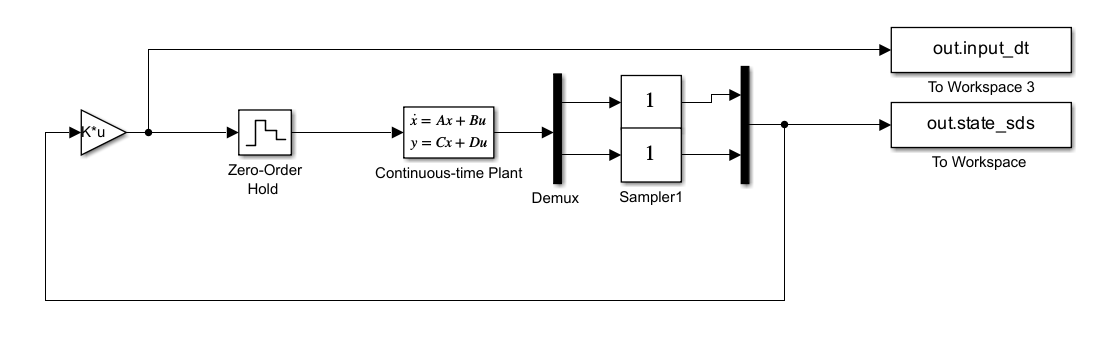

여기서 연속 시간 플랜트는 상태 변수 모델인 `Gp_ss` 에서, 상태 변수와 관련된 연속 시간 상태 방정식


$$\dot{\bf x}^c(t)= {\bf A} {\bf x}^c(t) + {\bf B} u^c(t)$$


를 표현하며, 전체 상태 변수 ${\bf x}^c(t)$를 출력하기 위해 해당 블록의 C, D 파트는 각각 $\left[\matrix{1 & 0 \cr 0 & 1}\right]$과 $\left[ \matrix{0 \cr 0} \right]$로 설정하였습니다.

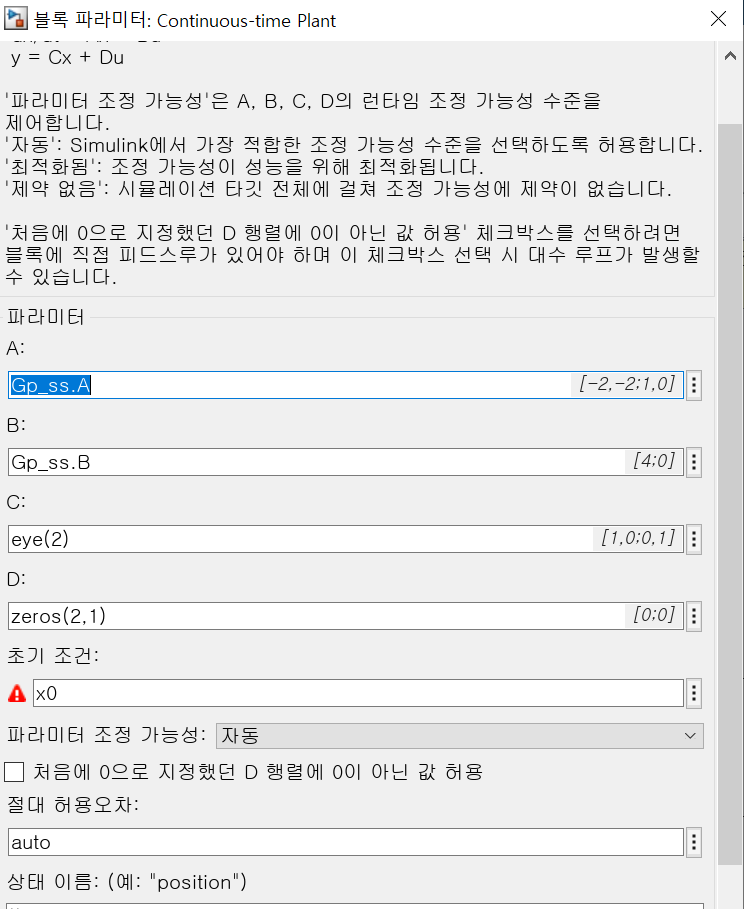

한편 유의미한 제어결과를 관찰하기 위해, 초기값 ${\bf x}^c(0)$을 다음과 같이 설정합니다. 

x0 = [1; -1];

위의 상태 변수 모델의 출력은 ${\bf x}^c(t)$는 샘플러를 통해 샘플링되어 


$${\bf x}^d(k):={\bf x}^c(kT)$$


를 얻게 되며, 이를 피드백받아서 Gain 블록에 곱하여 상태 궤환 제어를 수행하게 됩니다. 

(이 과정에서 상태변수 각각을 샘플링하는 방식으로 구현되어 있어서, 2개의 샘플러와 mux, demux 블록이 사용되었습니다.)

이때 Gain 블록은 아래와 같이 설정되어 있습니다.

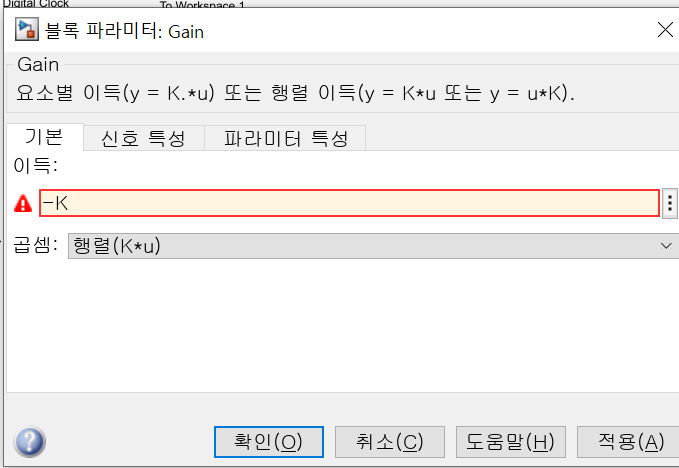

여기서 저희의 이득값인 $-{\bf K}$가 행렬이기 때문에 "곱셈" 옵션을 꼭 "행렬 (K*u)"로 지정해야 합니다. 

이를 유념하여 구현한 후, 시뮬레이션을 돌려보면 아래와 같습니다.

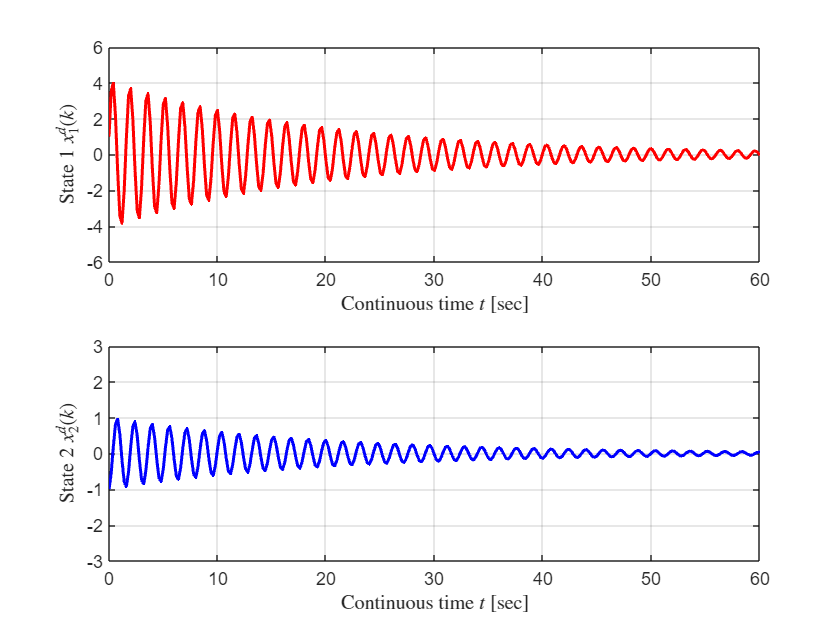

T_sim = 60;
dt_sim = 0.001;   

sim('sim_topic3.slx');
simout = ans;
time_dt_sim3 = simout.time_dt;
state_sds_sim3 = simout.state_sds;
input_dt_sim3 = simout.input_dt;

figure();
subplot(2,1,1)
    plot(time_dt_sim3, state_sds_sim3(:,1), 'r', 'LineWidth', 1.5);
    xlabel('Continuous time $t$ [sec]','Interpreter','latex');
    ylabel('State 1 $x^d_1(k)$','Interpreter','latex');
    xlim([0 T_sim]); 
    ylim([-6 6]);
    grid on;
subplot(2,1,2)
    plot(time_dt_sim3, state_sds_sim3(:,2), 'b', 'LineWidth', 1.5);
    xlabel('Continuous time $t$ [sec]','Interpreter','latex');
    ylabel('State 2 $x^d_2(k)$','Interpreter','latex');
    xlim([0 T_sim]); 
    ylim([-3 3]);
    grid on;

위와 같이 전체 시스템이 안정하게 제어됨을 확인할 수 있습니다. 

수렴속도 등은 제어기 이득을 설계하는 과정에서 등장한 고유값의 위치를 적정히 조정함으로써 재설정할 수 있습니다. 